# **Projet Pilote Automatique: **

# Conception d'un pilote automatique pour le mouvement longitudinal d'un avion (Boeing 737)

**Cours: MGA804**

**Session:** Automne 2024

**Équipe: **

- **Étudiant.e n°1:** Nom, Prénom (Matricule)

- **Étudiant.e n°2:** Nom, Prénom (Matricule)

**Sommaire**

## **Introduction**

Dans ce projet, on vous demande de réaliser un pilote automatique pour le mouvement longitudinal d'un avion civil. Les modes du pilote automatique que vous devez concevoir sont:

- un mode de maintien de la vitesse verticale (*Vertical Speed*),

- un mode de maintien de l'altitude (*Altitude Hold*).

Votre pilote automatique devra également inclure:

- un système d'augmentation de la stabilité (SAS) pour la vitesse en tangage (*Pitch Damper*),

- un système d'augmentation de la contrôlabilité (CAS) pour l'accélération normale (*Normal Acceleration CAS*).

Le livrable de ce projet est ce fichier .mlx, qui contient l'ensemble de votre étude. Vous devez également remettre un schéma Simulink final qui contient tout votre système de pilotage automatique (SAS + CAS + AP).

Vos fichiers devront être remis dans un dossier *.zip, et remis sur Moodle avant la date de remise (voir section sur Moodle).

## Simulateur de vol (FlightGear) [Non obligatoire]

Le modèle Simulink est capable de s’interfacer avec le simulateur de vol FlightGear. 

FlightGear est un simulateur de vol libre, open-source, et gratuit. Il ne nécessite pas d’avoir une configuration particulière pour fonctionner. FlightGear peut être téléchargé gratuitement sur le site : [https://www.flightgear.org/.](https://www.flightgear.org)

Une fois téléchargé, il est possible d’ajouter des avions dans le « hangar » de FlightGear en cliquant sur l’onglet « Aéronef » en haut à gauche, puis de faire une recherche sur l’avion que l’on souhaite ajouter. Dans le cadre de ce projet, nous utiliserons l’avion « Boeing 747-400 ».

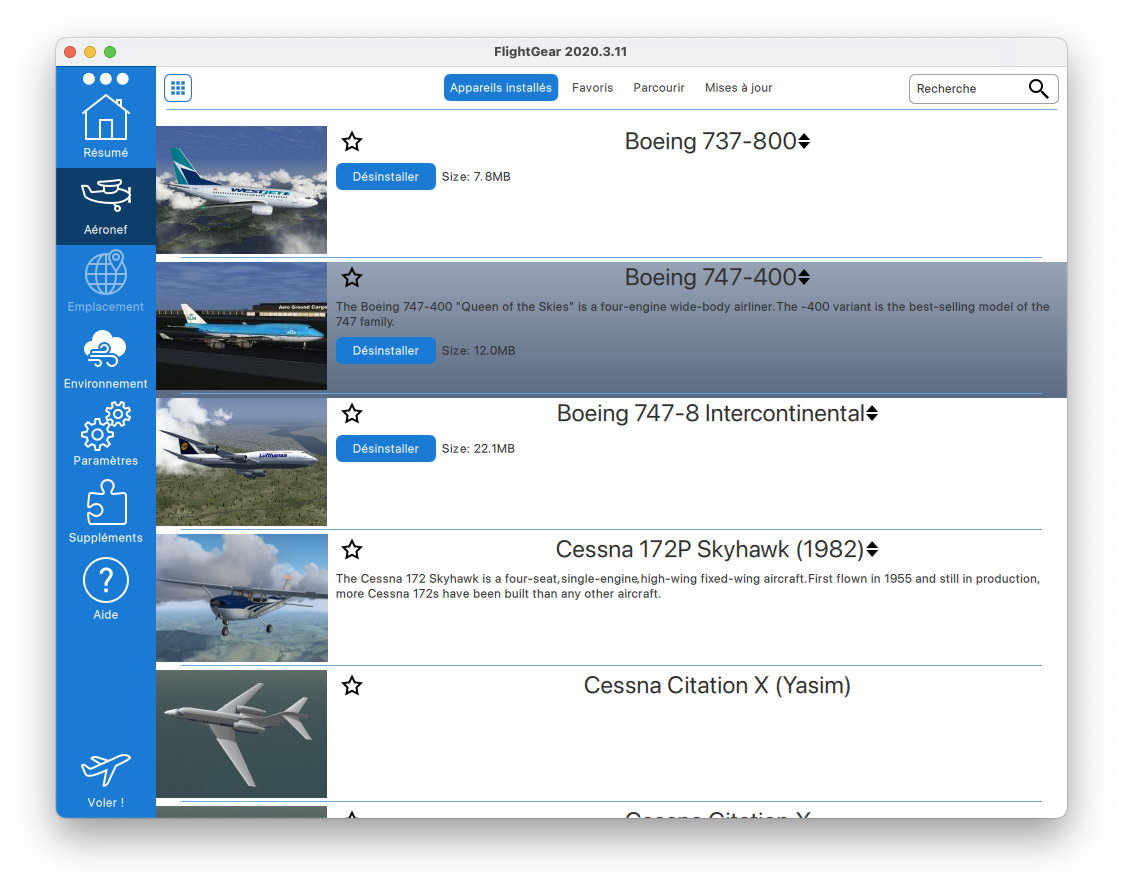

Pour télécharger un avion, il suffit de cliquer sur le bouton « **Installer** ».

Une fois l’avion sélectionné, il faut ajouter une ligne de commande dans FlightGear pour spécifier au simulateur de vol qu’il sera contrôlé par Simulink en utilisant un protocole de communication TCP/IP. Pour cela, il suffit d’ajouter les lignes de codes suivantes :

dans la section « **Paramètres supplémentaires** » de l’onglet « **Paramètres** ». 

Une fois le simulateur configurer, il suffit de cliquer sur « Voler ! » pour lancer la simulation. L’avion devrait alors bouger à chaque fois que le modèle Simulink est exécuté. 

**Note :** pour utiliser le simulateur de vol librement (i.e., sans Matlab/Simulink), il faut effacer la ligne de commande dans la section « **Paramètres supplémentaires** ».

## Données du projet pour le mouvement longitudinal

On considéere le modéle longitudinal d'un avion civil pour la condition de vol $h$ = 10000 m et $V_{T,0} = V_0$ = 209.6  m/s ($M$= 0.7).

close all; 
clear;
clc

addpath('Modele Simulink/')

% Déclaration de la conditions de vol
g_0     = 9.81;    % m/s^2
h_0     = 10000;   % m
V_0     = 209.6;   % m/sec
theta_0 = 0.0490;  % rad

% Calcul de u_0 et w_0
u_0 = V_0*cos(theta_0);
w_0 = V_0*sin(theta_0);


## Définition du modèle d'état pour le mouvement longitudinal

On considére le modèle d'état longitudinal suivant:


$$\Delta\mathbf{\dot{x}} = \mathbf{A}_{\text{lon}} \Delta \mathbf{x} + \mathbf{B}_{\text{lon}} \Delta \mathbf{u} $$



$$\Delta\mathbf{y} = \mathbf{C}_{\text{lon}} \Delta \mathbf{x} + \mathbf{D}_{\text{lon}} \Delta \mathbf{u} $$


avec $\Delta \mathbf{x} = \left[ \Delta u \ \Delta w \ \Delta q \ \Delta \theta \right]^{T}$ et $\Delta \mathbf{u} = \left[ \Delta \delta_e \  \Delta \delta_t  \right]^{T}$. 

Le vecteur de sortie est choisit tel que :  $\Delta \mathbf{y} = \left[ \Delta V_T \ \Delta V_z \ \Delta a_n \ \Delta q \right]^{T}$, avec:


$$\Delta V_T = \cos(\theta_0) \Delta u + \sin(\theta_0)\Delta w$$



$$\Delta V_Z = \sin(\theta_0) \Delta u - \cos(\theta_0)\Delta w + V_{T,0}\Delta \theta$$



$$\Delta a_n = -\left( \Delta \dot{w} - u_0 \Delta q\right)/g_0$$


où $\Delta a_n$ est l'accélération normale suivant l'axe vertical de l'avion, **exprimé en "g"**.

Les matrices $\mathbf{A}_{\text{lon}}$ et $\mathbf{B}_{\text{lon}}$ de votre avion **vous sont données** dans le code ci-dessous: 

% Matrice A pour le mouvement longitudinal de l'avion:
A_lon = [-0.0028    0.0523   -9.6542   -9.7949
         -0.0563   -0.3807  167.7545   -0.4808
          0.0003   -0.0047   -0.5113    0
          0         0         1.0000    0      ];
      
% Matrice B pour le mouvement longitudinal de l'avion:
B_lon  = [ 0.0445    4.1490
          -2.9749    0.0404
          -1.8897    0.0001
           0         0];

## Partie 1 - Création du modèle en boucle ouverte de votre avion

Dans cette partie, vous devez créer votre modèle de l'avion que vous renommerez `avion_longi`.

- **Indice 1: **vous devez trouver les matrices $\mathbf{C}_{\text{lon}}$ et $\mathbf{D}_{\text{lon}}$ pour observer les variables de sortie $\Delta \mathbf{y} = \left[ \Delta V_T \ \Delta V_z \ \Delta a_n \ \Delta q \right]^{T}$. 

- **Indice 2: **vous n'avez pas besoin d'avoir les dérivées de stabilité pour cette question. 

**Réponse:** 

% développement + code + commentaire

## Partie 2 - Création du modèle pour les actionneurs et les moteurs

On suppose que l'actionneur pour les élévateurs (gouvernes de profondeur) est modélisable par une fonction de transfert de premier ordre, tel que:


$$H_{\delta_e}(s) = \displaystyle\frac{\Delta \delta_e}{\Delta \delta_{e,c}} = \displaystyle\frac{1}{0.1s + 1}$$


et que les moteurs ont la dynamique suivant:


$$H_{\delta_t} = \displaystyle\frac{\Delta\delta_t}{\Delta \delta_{t,c}}= \displaystyle\frac{1}{3.5s + 1}$$


Créer les fonctions de tranfert $H_{\delta_e}(s)$et $H_{\delta_t}(s)$correspondant à la dynamique des acitionneurs et des moteurs:

**Réponse:** 

% développement + code + commentaire

## Partie 3 - Création du modèle en boucle ouverte de votre avion avec les actionneurs + moteurs.

Réaliser le schéma Simulink ci-dessous, et renommez le `Avion_act_mot`. 

Ce schéma représente votre avion en boucle ouverte avec les actioneurs et les moteurs, et sera le **point de départ** de toute votre étude.

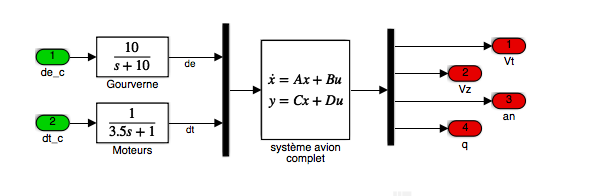

**IMPORTANT À SAVOIR:**

En réalisant des schéma Simulink comme celui-ci à chaque étape, vous serez en mesure de calculer les fonctions de transferts équivalentes grâce à la fonction `linmod` de Matlab. 

Pour obtenir une fonction de transfert (ou le modèle d'état) à partir d'un schéma Simulink, vous devez spécifier vos entrées (en vert dans la figure) et vos sorties (en rouge dans le figure). Par la suite, vous enregistrez votre modèle, puis dans Matlab, vous utilisez la fonction `linmod`:

% % Récupération des matrices A, B, C, D correspondantes au Simulink:
%   [A, B, C, D] = linmod('Avion_act_mot');
%
% % Création du modèle de l'avion + actionneurs + moteurs
%   avion_act_mot= ss(A, B, C, D);
%
% % Création d'une fonction de transfert à partir de A, B, C, D:
%   [num, den] = ss2tf(A, B, C, D, idx_entree);       % idx_entree = entrée que l'on veut.
%   fonction_transfert = tf(num(idx_sortie, :), den); % idx_sortie = sortie que l'on veut.


## Partie 4 - Analyse du modèle en boucle ouverte

Réalisez une analyse de la stabilité de votre avion en boucle ouverte (dynamique naturelle sans actionneur et moteur). Pour cela, vous devez:

- Faire une étude de la stabilité de votre avion ;

- Faire une étude des qualités de manoeuvrabilité de votre avion ;

- Donne une conclusion ou un commentaire général sur votre étude.

**Réponse:** 

% développement + code + commentaire

## Partie 5 - Création du modèle réduit pour le *Short Period*

On souhaite créer le modèle réduit pour le mode *Short Period:*


$$\Delta\mathbf{\dot{x}_{sp}} = \mathbf{A_{sp}} \Delta \mathbf{x_{sp}} + \mathbf{B_{sp}} \Delta \mathbf{u_{sp}} $$



$$\Delta\mathbf{y_{sp}} = \mathbf{C_{sp}} \Delta \mathbf{x_{sp}} + \mathbf{D_{sp}} \Delta \mathbf{u_{sp}} $$


avec $\Delta \mathbf{x_{sp}} = \left[\Delta w \ \Delta q \right]^{T}$, $\Delta \mathbf{u_{sp}} =  \Delta \delta_e$, et le vecteur de sortie $\Delta \mathbf{y_{sp}} = \left[ \Delta a_n \ \Delta q \right]^{T}$.

Donnez les matrices `A_sp`, `B_sp`, `C_sp`, et `D_sp` correspondant au mode *Short Period*. Construisez le modèle d'état réduit de l'avion.

**Réponse:** 

% développement + code + commentaire

## Partie 6 - Conception d'un CSAS pour l'accélération normale à partir du modèle réduit

On suppose que le pilote contrôle l'accélération normale de l'avion par l'intermédiare de son manche (sidestick). On souhaite alors réaliser un système CSAS (CAS + SAS) pour l'accélération normale avec pour SAS un *pitch damper* sur la vitesse en tangage $\Delta q$.

**Voici votre cahier des charges pour le système CSAS:**

Votre système SAS pour la vitesse en tangage devra satisfaire les contraintes suivantes:

- Assurer la stabilité du mode *Short Period*,

- Assurer un amortissement minimal de 0.8 pour le mode *Short Period*.

Pour le CSAS (CAS+SAS), il devra satisfaire les contraintes suivantes:

- Un temps de réponse à 2% **de l'ordre** de 4 secondes,

- Limiter au mieux que possible le dépassement.

Vous devez utilisez le lieu des racines pour réaliser votre étude. Il est **interdit d'utiliser les outils **`pidtool`** et **`pidtune` (ou équivalent).

**Réponse:** 

% développement + code + commentaire

## Partie 7 - Validation du CSAS pour l'accélération normale sur le modèle complet

Une fois vos gains calculer, vous devez réaliser le schéma Simulink ci-dessous dans un nouveau fichier que vous renommerez `Avion_act_mot_csas`.

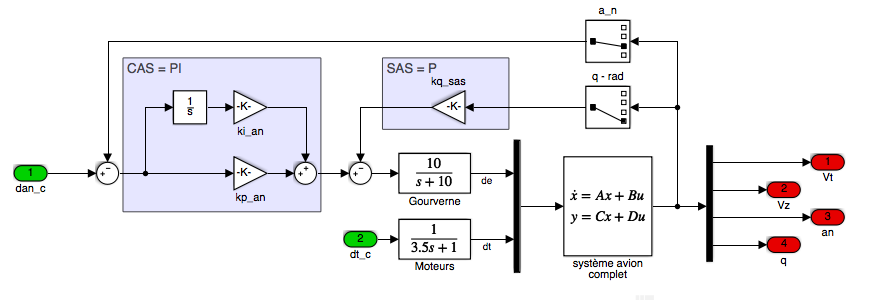

Trouver alors le modèle d'état du système avec le bouclage CSAS (CAS + SAS) en utilisant la fonction `linmod`.

Réaliser une simulation sur 20 secondes de votre avion avec le CSAS en imposant un échelon sur la commande en accélération normale qui vaut:

- 1 jusqu'à 10 secondes, 

- puis 0 entre 10 et 20 secondes.  

Vous devez affichez la réponse en accélération normale (supperposée avec l'accélération souhaitée) et en vitesse de tangage.

**IMPORTANT: **le rebouclage de votre CSAS pour l'accélération normale doit être effectué sur le modèle complet de l'avion (modèle 4x4).

**Réponse:** 

% développement + code + commentaire

## Partie 8 - Conception d'un autopilote pour le maintien la vitesse verticale (*Vertical Speed*)

On vous demande maintenant de réaliser un pilote automatique pour le maintien de la vitesse verticale de l'avion (*Vertical Speed*). Pour cela, vous devez:

- trouver le fonction de transfert $\Delta Vz(s)/ \Delta a_{n,c}(s)$,

- réaliser la conception d'un compensateur $C_{vz}(s)$ de type **proportionnel** ($k_{vz}$).

**Cahier des charges pour votre pilote automatique:**

- Être la plus simple possbile (correcteur le plus simple),

- Permettre de commander une vitesse verticale imposée par le pilote,

- Avoir une temps de réponse à 2% de l'ordre de 6 à 10 secondes,

- Vous devez utilisez l'outil `rltool` de Matlab.

**Indice:** faire une analyse pour $k_{vz} > 0$ et $k_{vz} < 0$ .

Vous devez produire une simulation à la fin de votre étude montrant les réponses de l'avion en vitesse verticale, accélération normale et vitesse pour une commande de type échelon sur la vitesse verticale qui vaut:

- 1 jusqu'à 20 secondes, 

- puis 0 entre 20 et 40 secondes.  

**Réponse:** 

% développement + code + commentaire

## Partie 9 - Conception d'un autopilote pour le maintien de la vitesse (*Auto-Throttle*)

En utilisant le dernier bouclage sur le CSAS + Vert. Speed, on vous demande de concevoir un pilote automatique pour le maintien de la vitesse $\Delta V_T$ de l'avion. Pour cela, vous devez:

- Trouver le fonction de transfert $\Delta V_{T}(s)/ \Delta \delta t_{c}(s)$,

- Réaliser la conception d'un compensateur $C_{VT}(s)$ de type **PI + Avance de phase**,

- Utiliser l'outils `rltool` pour la conception de votre compensateur.

Il n'est pas utilise d'ajouter une boucle interne pour l'accélération longitudinale, et vous supposerez le compensateur $C_{VT}(s)$ ci-dessous, 


$$C_{VT}(s) = k_{VT}\left[\frac{s+z_{VT}}{s+1}\right]$$


où le zéro $z_{VT}$ est à determiner dans la plage [-0.5; 0.0]

**Cahier des charges:**

- Être la plus simple possbile (un simple gain dans la chaine directe),

- Permettre de commander maintenir la vitesse de l'avion ($\Delta V_T$= 0),

- Avoir une temps de réponse à 2% de l'ordre de 6 à 10 secondes.

À la fin de cette partie, vous devrez refaire la même simulation que dans la partie précédente. Observez l'effet de votre compensateur sur la vitesse.

**Réponse:** 

% développement + code + commentaire

## Partie 10 - Conception d'un autopilote pour le maintien d'altitude (*Altitude Hold*)

Pour terminer, on vous demande de réaliser un dernier bouclage pour concevoir un pilote automatique pour le maintien de l'altitude. Pour cela, vous utiliserez le correcteur de type PI + Avance de phase ci-dessous:


$$C_h(s) = k_h\left[\frac{s+z_h}{s+1}\right]$$


où $z_h$ est à déterminer dans la plage [-1, 0]. Pour cela, vous devez:

- trouver le fonction de transfert $\Delta h(s)/ \Delta Vz{c}(s)$,

- réaliser la conception d'un compensateur $C_{h}(s)$.

Pour trouver la fonction de transfert $\Delta h(s)/ \Delta Vz{c}(s)$, vous pouvez vous utilisez un schéma Simulink en remarquant que :


$$Vz = \frac{dh}{dt} \Rightarrow \Delta h(s) = \left[\frac{1}{s}\right] \Delta V_z(s)$$


**Cahier des charges du pilote automatique:**

- Permettre de commander l'altitude de l'avion,

- Avoir une temps de réponse à 2% de l'ordre de 10 secondes.

**Réponse:** 

% développement + code + commentaire
